% duck = imread("IMAGE032.jpg");
% imshow(duck);
% hsv_duck = rgb2hsv(duck);
% imshow(hsv_duck)
% 
% hue_duck = hsv_duck(:,:,1);
% 
% 
% sat_duck = hsv_duck(:,:,2);
% val_duck = hsv_duck(:,:,3);
% 
% imshow(hue_duck)
% imshow(sat_duck)
% imshow(val_duck)
% 
% % val_duck(val_duck < 0.4) = 0 
% imhist(val_duck)
% imshow(val_duck

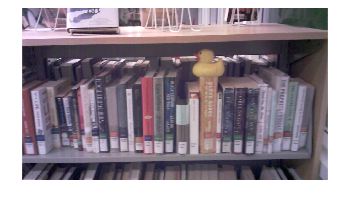

% Find Sub-frames
clear()
clf()
duck = imread("IMAGE032.jpg");
imshow(duck)

W_h = length(duck(1,:,:))

W_h = 1280

W_v = length(duck(:,1,:))

W_v = 720

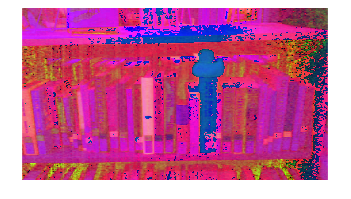

M = 160;
N = 180;
N_C = floor(W_h/M);
N_R = floor(W_v/M);

hsv_duck = rgb2hsv(duck);
imshow(hsv_duck)


h_duck = hsv_duck(:,:,1);
s_duck = hsv_duck(:, :, 2);
v_duck = hsv_duck(:, :, 3);

h_sort_rows = subframe_ranking(h_duck, N_C, M, N_R, N)

h_sort_rows =     23
    19
    18
    15
    24
    30
    28
    20
    31
    17


s_sort_rows = subframe_ranking(s_duck, N_C, M, N_R, N)

s_sort_rows =     12
     3
    23
    28
    21
    31
    32
    19
    13
    25


v_sort_rows = subframe_ranking(v_duck, N_C, M, N_R, N)

v_sort_rows =      2
     1
    16
    25
     3
     4
    14
    28
     9
    11



sorted_rows = h_sort_rows + s_sort_rows + v_sort_rows

sorted_rows =     37
    23
    57
    68
    48
    65
    74
    67
    53
    53



[min_val, min_idx] = min(sorted_rows)

min_val = 23

min_idx = 2

for index = 1 : N_C * N_R
    min_index_col = ceil(index / 4);
    min_index_row = mod(index, 4);
    
    horz_start = max((min_index_col - 1) * M, 1);
    horz_end = horz_start + M;
    vert_start = max((min_index_row - 1) * N, 1);
    vert_end = vert_start + N;
    
    region = hsv_duck(vert_start:vert_end, horz_start:horz_end, :);
    v_region = region(:,:,3);
    mean_region = mean(v_region,"all");
%     figure()
%     imshow(hsv2rgb(region))
    if mean_region < 0.35
        sorted_rows(index) = inf;
    end 
end 
sorted_rows

sorted_rows =     37
   Inf
    57
    68
    48
   Inf
    74
    67
    53
    53


% mask = zeros(size(sorted_rows));
% 
% mask(min_idx) = 1;
% 
% mask_reshaped = reshape(mask, N_R, N_C);
% 
% imagesc(mask_reshaped);

for index = 1 : N_C * N_R
    min_index_col = ceil(index / 4);
    min_index_row = mod(index, 4);
    
    horz_start = max((min_index_col - 1) * M, 1);
    horz_end = horz_start + M;
    vert_start = max((min_index_row - 1) * N, 1);
    vert_end = vert_start + N;
    
    region = hsv_duck(vert_start:vert_end, horz_start:horz_end, :);
    v_region = region(:,:,3);
    mean_region = mean(v_region,"all");
%     figure()
%     imshow(hsv2rgb(region))
    if mean_region > 0.6
        sorted_rows(index) = inf;
    end 
end 
sorted_rows

sorted_rows =    Inf
   Inf
    57
   Inf
   Inf
   Inf
    74
   Inf
   Inf
    53


[min_val, min_idx] = min(sorted_rows)

min_val = 28

min_idx = 27

%min_idx = 18
min_index_col = ceil(min_idx / 4);
min_index_row = mod(min_idx, 4);

horz_start = max((min_index_col - 1) * M, 1);
horz_end = horz_start + M;
vert_start = max((min_index_row - 1) * N, 1);
vert_end = vert_start + N;

region = hsv_duck(vert_start:vert_end, horz_start:horz_end, :);
v_region = region(:,:,3);
mean_region = mean(v_region,"all")

mean_region = 0.5570

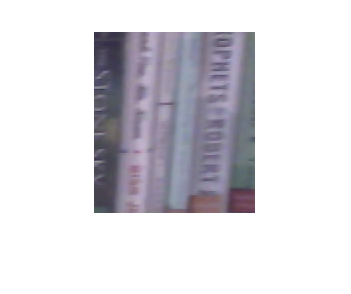

figure()
imshow(hsv2rgb(region))

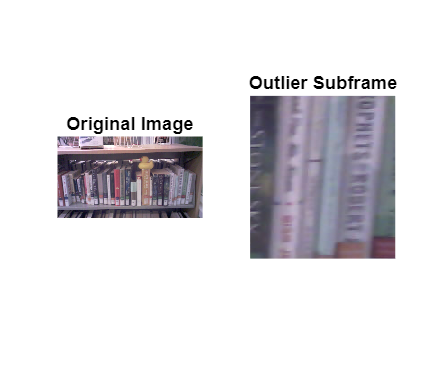

%graphing
subplot(1,2,1)
imshow(duck)
title("Original Image")

subplot(1,2,2)
imshow(hsv2rgb(region))
title("Outlier Subframe")

function sortrws = subframe_ranking(duck, N_C, M, N_R, N)
    test_duck = duck([1:3],[1:4]);
    subframes = [];
    for i = [0:N_C-1]
        column_range = [1+i*M:1+i*M+(M-1)];
        duck(1,column_range);
        %i
        for j = [0:N_R-1]
            rows_range = [1+j*N:1+j*N+(N-1)];
            duck(rows_range,1);
            %j
            subgrapg = duck(rows_range,column_range);
            subframes = cat(3, subframes, subgrapg);
        end 
    end 
    % Sum Subframes
    sum_subframe = sum(subframes,1);
    sum_subframe = sum(sum_subframe,2);
    reshape_subframe = reshape(sum_subframe, [4,8]);
    neighbors = zeros(size(reshape_subframe));
    for i = 1:size(reshape_subframe,1)
        for j = 1:size(reshape_subframe,2)
            num_neigh = 8;
            try
                neighbors(i,j) = neighbors(i,j) + reshape_subframe(i,j+1);
            catch 
                num_neigh = num_neigh - 1;
            end 
    
            try 
                neighbors(i,j) = neighbors(i,j) + reshape_subframe(i+1,j+1);
            catch 
                num_neigh = num_neigh - 1;
            end 
    
            try 
                neighbors(i,j) = neighbors(i,j) + reshape_subframe(i+1,j);
            catch 
                num_neigh = num_neigh - 1;        
            end 
    
            try 
                neighbors(i,j) = neighbors(i,j) + reshape_subframe(i+1,j-1);
            catch 
                num_neigh = num_neigh - 1;
            end 
    
            try 
                neighbors(i,j) = neighbors(i,j) + reshape_subframe(i,j-1);
            catch 
                num_neigh = num_neigh - 1;
            end 
    
            try 
                neighbors(i,j) = neighbors(i,j) + reshape_subframe(i-1,j-1);
            catch 
                num_neigh = num_neigh - 1;
            end 
    
            try 
                neighbors(i,j) = neighbors(i,j) + reshape_subframe(i-1,j);
            catch
                num_neigh = num_neigh - 1;
            end 
    
            try 
                neighbors(i,j) = neighbors(i,j) + reshape_subframe(i-1,j+1);
            catch 
                num_neigh = num_neigh - 1;
            end 
            neighbors(i,j) = neighbors(i,j)/num_neigh;
        end 
    end 
    neighbors;
    
    % Difference
    diff = abs(reshape_subframe - neighbors);
    diff = reshape(diff,[32,1]);
    [sorted_val, index] = sort(diff, "descend");
    
    rankings = [(1:32)', index];
    
    sorted_rws = sortrows(rankings, 2);
    sortrws = sorted_rws(:, 1);
end